# Read 2010 raw data

inline 1037

## Introduction

**Author**: Ivan Abakumov

Freie Universität Berlin

**Publication date**: 8th May 2019

**E-mail**: [abakumov_ivan@mail.ru](mailto:abakumov_ivan@mail.ru)

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

filename = '/data2/ST10010/Raw_data/ST10010+NAV_MERGE/ST100010_1150780_40203_chw_inline1037_P_only.sgy'

filename = '/data2/ST10010/Raw_data/ST10010+NAV_MERGE/ST100010_1150780_40203_chw_inline1037_P_only.sgy'

data = read_segy_file(filename)

data = struct with fields:
                      type: 'seismic'
                       tag: 'unspecified'
                      name: 'ST100010_1150780_40203_chw_inline1037_P_only'
                      from: '/data2/ST10010/Raw_data/ST10010+NAV_MERGE/ST100010_1150780_40203_chw_inline1037_P_only.sgy'
               line_number: 1
               reel_number: 1
         traces_per_record: 1
                     first: 0
                      last: 9998
                      step: 2
                     units: 'ms'
                    traces: [5000×57600 double]
                      null: []
                   history: {'15-Jul-2019 14:12:52 '  [1077]  'FINALIZE_SEISMIC_DATASET'  '/data2/ST10010/Raw_data/ST10010+NAV_MERGE/ST100010_1150780_40203_chw_inline1037_P_only.sgy'}
               header_info: {18×3 cell}
                   headers: [18×57600 double]
    fp_format_of_segy_file: 'ieee-be'



headers = get_segy_headers(data);
headers.rx = headers.rx/10;  % scaleco = -10
headers.ry = headers.ry/10; 
headers.sx = headers.sx/10;
headers.sy = headers.sy/10;

headers.cdpx = (headers.sx + headers.rx)/2;
headers.cdpy = (headers.sy + headers.ry)/2;


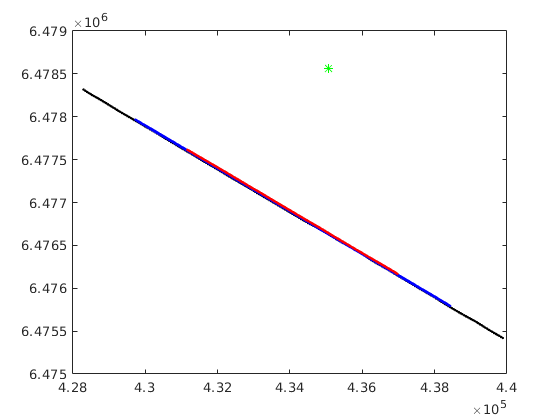

figure(1)
plot(headers.sx, headers.sy, 'k.');
hold on 
plot(headers.cdpx, headers.cdpy, 'b.')
plot(headers.rx, headers.ry, 'r.')
plot(435050.94, 6478558.87, 'g*')       % position of TLP

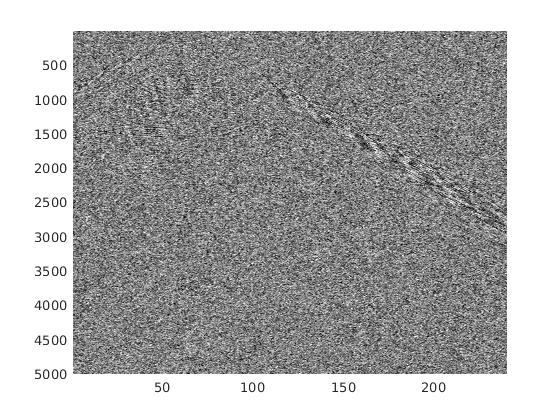


figure(2)
ind = headers.tracf==1;
pcolor(data.traces(:,ind))
set(gca, 'YDir','reverse')
shading interp
colormap gray
caxis([-100 100])